# XTD_A2: Persistence Model Fitting Analysis

load('.\XTD_All_PI_PO.mat');
% load('D:\WorkBigDataFiles\PFC\XTD_All_PO_PO.mat');
% load('D:\WorkBigDataFiles\PFC\XTD_DL_PI_PO.mat');

cMap = load('roma.mat'); % flip
cMap = cMap.(cell2mat(fieldnames(cMap)));
cMap = flipud(cMap);
cMapNanW = cMap;
cMapNanW(1,:) = ones(1,3);
%#ok<*UNRCH>
rbDivMap = diverging_map(0:0.01:1,[0 0.4 0.8], [0.8 0 0.4]);

objTimeVect = mlb.obsvTimeVect-mlb.obsvTimeVect(1);

## Compile Data

persFit_Trial = cell(mlb.seqLength, 1, length(fileDirs));
persFit_Interval = cell(mlb.seqLength, 1, length(fileDirs));
for ani = 1:length(fileDirs)
    curAni_D = xtd_D(:,:,ani);
    curAni_TrialMask = mask_Trial(:,ani);
    curAni_IntMask = mask_Int(:,ani);
    for pos = 1:mlb.seqLength
        curPos_D = curAni_D{pos,pos};
        curPos_TrialMask = curAni_TrialMask{pos};
        curPos_IntMask = curAni_IntMask{pos};
        curPos_persFit_Trial = nan(size(curPos_D,3), length(mlb.obsvTimeVect));
        curPos_persFit_Interval = nan(size(curPos_D,3), length(mlb.obsvTimeVect));
        for trl = 1:size(curPos_D,3)
            curTrial_D = curPos_D(:,:,trl);
            curTrial_TrialMask = curPos_TrialMask(:,trl);
            curTrial_IntMask = curPos_IntMask(:,trl);

            trialDynCap = sum(curTrial_TrialMask)-1;
            trialPeriod = zscore(curTrial_D(curTrial_TrialMask,curTrial_TrialMask), 0, 'all');
            for d = 1:trialDynCap-1
                tempDyn = zscore(triu(true(sum(curTrial_TrialMask)), d*-1) & tril(true(sum(curTrial_TrialMask)), d), 0, 'all');
                curPos_persFit_Trial(trl,d) = pdist([trialPeriod(:)';tempDyn(:)'], 'cosine');
            end
            itiDynCap = sum(curTrial_IntMask)-1;
            itiPeriod = zscore(curTrial_D(curTrial_IntMask,curTrial_IntMask), 0 , 'all');
            for d = 1:itiDynCap-1
                tempDyn = zscore(triu(true(sum(curTrial_IntMask)), d*-1) & tril(true(sum(curTrial_IntMask)), d), 0, 'all');
                curPos_persFit_Interval(trl,d) = pdist([itiPeriod(:)';tempDyn(:)'], 'cosine');
            end
        end
        persFit_Trial{pos,1,ani} = curPos_persFit_Trial;
        persFit_Interval{pos,1,ani} = curPos_persFit_Interval;
    end
end


## Plot Model Fits

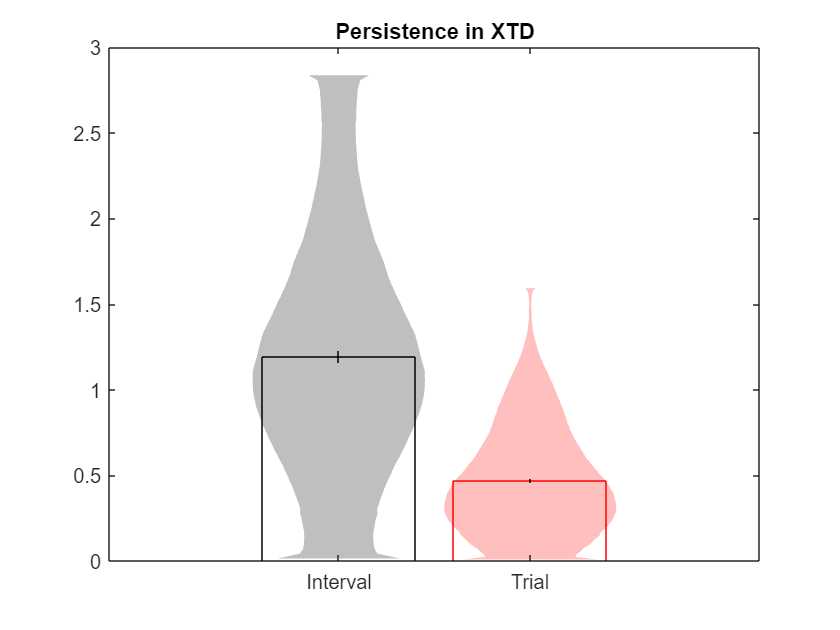

posCollapseLog = true(mlb.seqLength,1,length(fileDirs));
posCollapseLog(1,1,:) = false;
posCollapseLog(mlb.seqLength,1,:) = false;

temp_persFit_Trial = cell2mat(persFit_Trial(posCollapseLog));
temp_persFit_Interval = cell2mat(persFit_Interval(posCollapseLog));
% figure;
% mlb.PlotMeanVarLine(1:length(mlb.obsvTimeVect),temp_persFit_Trial,1,0.05,'k');
% mlb.PlotMeanVarLine(1:length(mlb.obsvTimeVect),temp_persFit_Interval,1,0.05,'r');
[~,trialBestFitNdx]=find(temp_persFit_Trial==repmat(min(temp_persFit_Trial,[],2),[1,size(temp_persFit_Trial,2)]));
[~,intervalBestFitNdx]=find(temp_persFit_Interval==repmat(min(temp_persFit_Interval,[],2),[1,size(temp_persFit_Interval,2)]));
intervalPersistDur = objTimeVect(intervalBestFitNdx);
trialPersistDur = objTimeVect(trialBestFitNdx);

figure;
mlb.PlotMeanVarViolin(1,intervalPersistDur,1,0.05,'k');
mlb.PlotMeanVarViolin(2,trialPersistDur,1,0.05,'r');
set(gca, 'xtick', 1:2, 'xticklabels', [{'Interval'}, {'Trial'}]);
title('Persistence in XTD')